syms p
% вводим разомкнутую систему w1
w1 = expand((p-1)*(p-2)*(p-3)*(p-(-4+2*1i))*(p-(-4-2*1i)))

$$w1 = p^{5}+2\,p^{4}-17\,p^{3}-38\,p^{2}+172\,p-120$$

w1coeff = sym2poly(w1) %коэффы для tf

w1coeff =      1     2   -17   -38   172  -120


roots(sym2poly(w1))

ans =   -4.0000 + 2.0000i
  -4.0000 - 2.0000i
   3.0000 + 0.0000i
   2.0000 + 0.0000i
   1.0000 + 0.0000i


% замкнутая неустойчивая w1
w1clos = expand((p-2)*(p+3)*(p+4)*(p-(-4+2*1i))*(p-(-4-2*1i)))

$$w1clos = p^{5}+13\,p^{4}+58\,p^{3}+60\,p^{2}-232\,p-480$$

w1u = w1clos - w1 %регулятор w1 бля

$$w1u = -11\,p^{4}-75\,p^{3}-98\,p^{2}+404\,p+360$$

w1ucoeff = sym2poly(w1u) %коэффы для tf

w1ucoeff =    -11   -75   -98   404   360


tf(1, w1coeff)

ans =
 
                       1
  -------------------------------------------
  s^5 + 2 s^4 - 17 s^3 - 38 s^2 + 172 s - 120
 
Continuous-time transfer function.



w = w1/(1+w1)

$$w = \frac{p^{5}+2\,p^{4}-17\,p^{3}-38\,p^{2}+172\,p-120}{p^{5}+2\,p^{4}-17\,p^{3}-38\,p^{2}+172\,p-119}$$

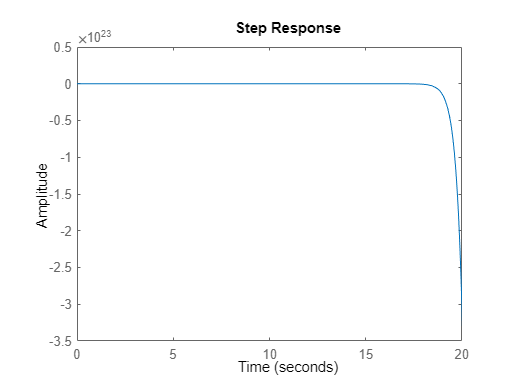

step([1 2 -17 -38 172 -120],[1 2 -17 -38 172 -119])

roots([1 2 -17 -38 172 -119])

ans =   -3.9992 + 1.9994i
  -3.9992 - 1.9994i
   2.9904 + 0.0000i
   2.0248 + 0.0000i
   0.9831 + 0.0000i



% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % 
% вводим разомкнутую систему w2
w2 = expand((p+1)*(p+2)*(p+3)*(p-(-4+2*1i))*(p-(-4-2*1i)))

$$w2 = p^{5}+14\,p^{4}+79\,p^{3}+214\,p^{2}+268\,p+120$$

w2coeff = sym2poly(w2) %коэффы для tf den

w2coeff =      1    14    79   214   268   120


roots(sym2poly(w2))

ans =   -4.0000 + 2.0000i
  -4.0000 - 2.0000i
  -3.0000 + 0.0000i
  -2.0000 + 0.0000i
  -1.0000 + 0.0000i


% замкнутая система w2
w2clos = expand((p-2)*(p-3)*(p-4)*(p-(-4+2*1i))*(p-(-4-2*1i)))

$$w2clos = p^{5}-p^{4}-26\,p^{3}+4\,p^{2}+328\,p-480$$

w2u = w2clos - w2 %регулятор w2 бля

$$w2u = -15\,p^{4}-105\,p^{3}-210\,p^{2}+60\,p-600$$

w2ucoeff = sym2poly(w2u) %коэффы для tf num

w2ucoeff =    -15  -105  -210    60  -600



% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % 
% вводим разомкнутую систему w3
w3 = expand((p+1)*(p+2)*(p-3)*(p-(-4+2*1i))*(p-(-4-2*1i)))

$$w3 = p^{5}+8\,p^{4}+13\,p^{3}-62\,p^{2}-188\,p-120$$

w3coeff = sym2poly(w3) %коэффы для tf den

w3coeff =      1     8    13   -62  -188  -120


roots(sym2poly(w3))

ans =    3.0000 + 0.0000i
  -4.0000 + 2.0000i
  -4.0000 - 2.0000i
  -2.0000 + 0.0000i
  -1.0000 + 0.0000i


% замкнутая система w3
w3clos = expand((p+2)*(p+3)*(p+4)*(p-(-4+2*1i))*(p-(-4-2*1i)))

$$w3clos = p^{5}+17\,p^{4}+118\,p^{3}+412\,p^{2}+712\,p+480$$

w3u = w3clos - w3 %регулятор w3

$$w3u = 9\,p^{4}+105\,p^{3}+474\,p^{2}+900\,p+600$$

w3ucoeff = sym2poly(w3u) %коэффы для tf num

w3ucoeff =      9   105   474   900   600
